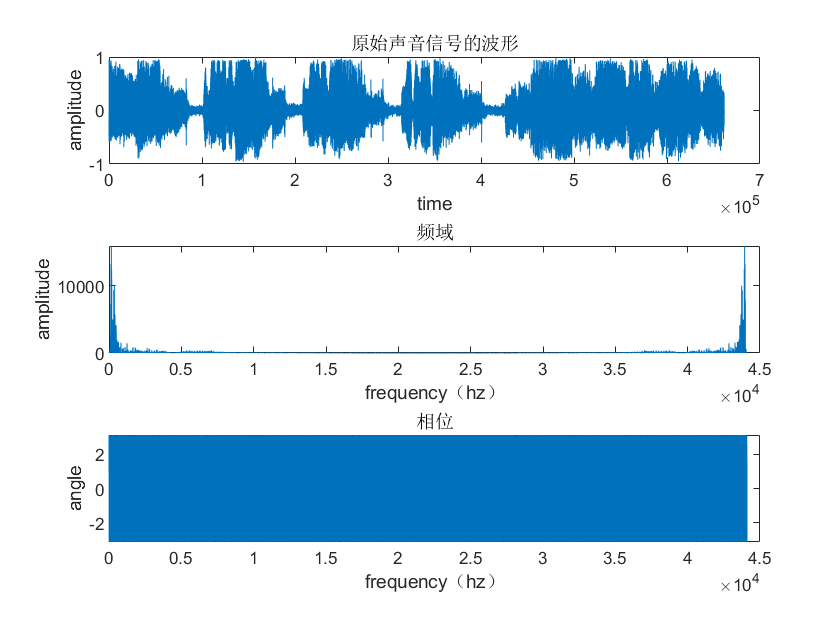

%---------------原始声音信号的产生--------------------------
clc;clear;

[x,fs]=audioread('cigarette_distance.wav');    %读入声音信号
x=x(:,1);       %取单声道做处理


%-------------原始信号特性-----------

[k]=fft(x);   %做傅立叶变换
[length]=size(k);
w=0:fs/length(1):fs-fs/length(1); 

figure(1);
subplot(3,1,1);
plot(x);
title('原始声音信号的波形');xlabel('time');ylabel('amplitude');
subplot(3,1,2);
plot(w,abs(k));
title('频域');xlabel('frequency（hz）');ylabel('amplitude');
subplot(3,1,3);
plot(w,angle(k));
title('相位');xlabel('frequency（hz）');ylabel('angle');

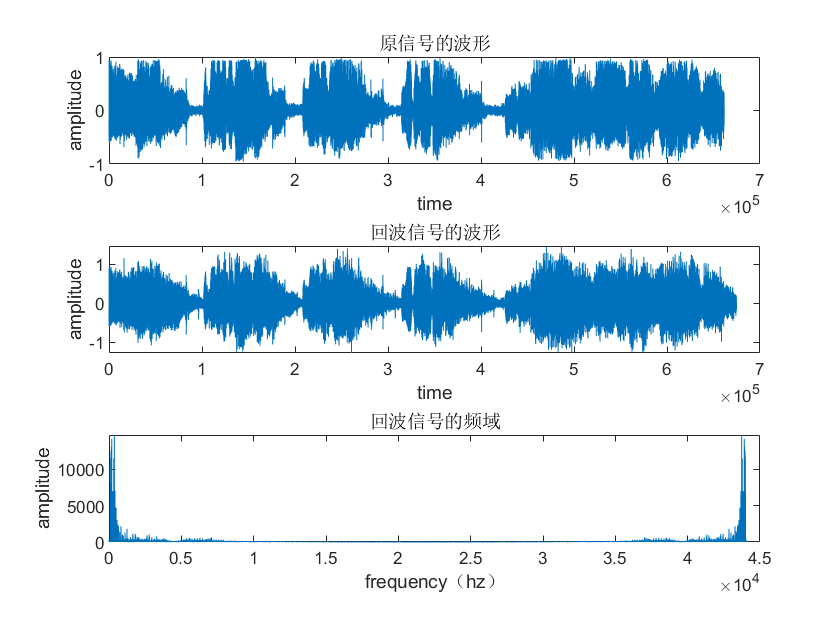

sound(x,fs);
pause(2); 


%-------------------------回波信号的产生----------------------------

delay=0.3;                 % 回波的延迟时间
N=fs*delay;                % 延迟量等于采样频率乘以延迟时间
Attenuation=0.6;           % 定义衰减系数

z=zeros(N,1);              % 构造一个N行一列的零矩阵
y=[x;z]+Attenuation*[z;x]; % 产生回波信号



%-----------回波信号的特性-----------
[k]=fft(y);   %做傅立叶变换
[length]=size(k);
w=0:fs/length(1):fs-fs/length(1); 


figure(2);
subplot(3,1,1);
plot(x);
title('原信号的波形');xlabel('time');ylabel('amplitude');
subplot(3,1,2);
plot(y);
title('回波信号的波形');xlabel('time');ylabel('amplitude');
subplot(3,1,3);
plot(w,abs(k));
title('回波信号的频域');xlabel('frequency（hz）');ylabel('amplitude');

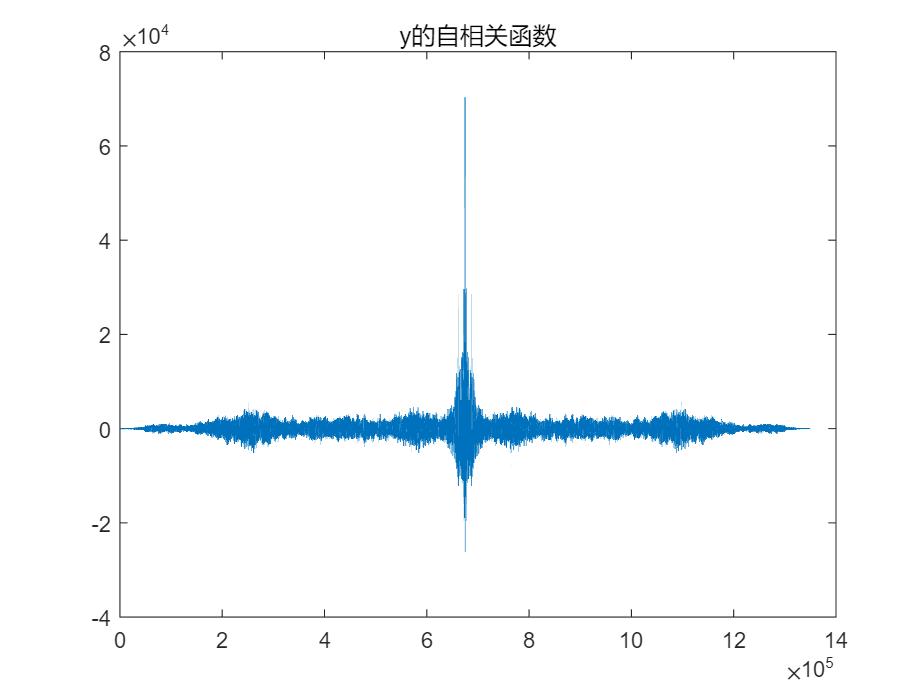

sound(y,fs);
audiowrite('Echo.wav',y,fs);
pause(2); 



%--------------------------参数估计-----------------------------------
y_corr=xcorr(y);%回波信号序列的自相关
figure(3);
plot(y_corr);
title('y的自相关函数');

[h1,h1_location]=max(y_corr);%找峰值及其坐标
y_corr(h1_location-fs/10:h1_location+fs/10)=zeros(2*fs/10+1, 1);
[h2,h2_location]=max(y_corr);%抹去零附近的值再找最值
N_delay=abs(h1_location-h2_location);%两个最大峰值的坐标之差的绝对值即为时间延迟
time_delay=N_delay/fs    %延迟的时间

time_delay = 0.3000

c=h1/h2;  %峰值比
a_estimated=(c-sqrt(c*c-4))/2   %估计衰减系数

a_estimated = 0.5098

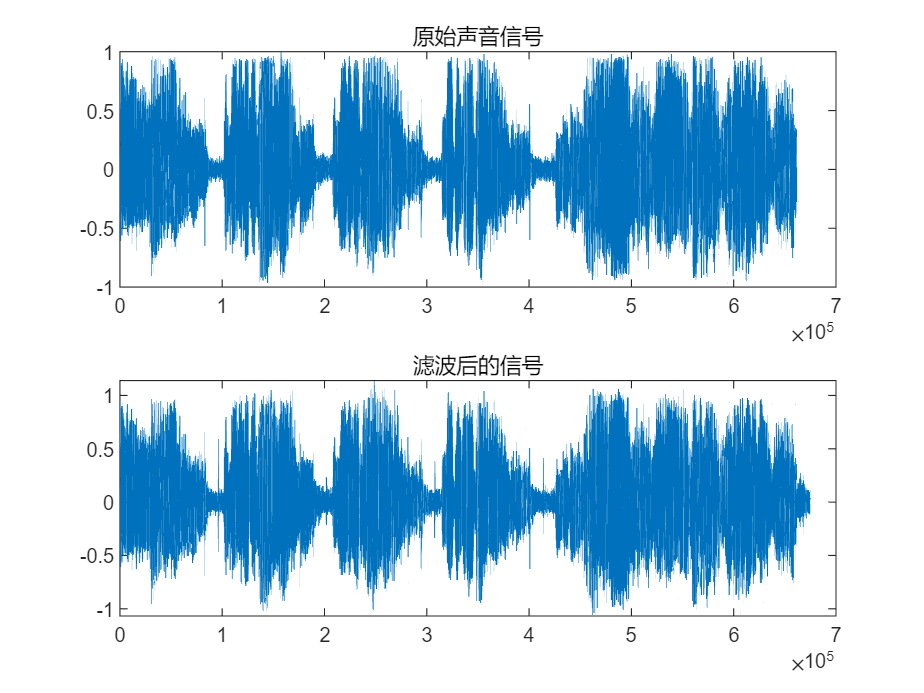




%---------------------------滤波--------------------------------------

num=[1;zeros(N_delay,1);a_estimated];     %设置滤波器参数
voice_DeEcho=filter(1,num,y);             %调用filter函数进行滤波
sound(voice_DeEcho,fs);
audiowrite('voice_DeEcho.wav',voice_DeEcho,fs);

%-----------------------滤波后信号与原信号的对比------------------------
figure(4);
subplot(2,1,1);
plot(x);
title('原始声音信号');
subplot(2,1,2);
plot(voice_DeEcho);
title('滤波后的信号');




%---------------------------距离估计-----------------------------------
v=340;  % 声音在空气中传播速度
distance=(v*N_delay)/(2*fs)  %   反射物的距离

distance = 51








%------------当a和N为随机数时的回波------------
%delay=0.1+0.1*floor(10*rand(1))    % 将延时时间设置为一个大于0.1的随机数，
                % 后面的floor是为了保证Delay是0.1的倍数，从而后面的N为整数
%N=fs*delay;  
%Attenuation=2*rand(1)-1        % 产生一个-1到1之间的衰减量，随机的